% Max Quant iBAQ data and sample classes imported 
load('Figure3necessary.mat', 'dfresh')
load('Figure3necessary.mat', 'genes')
load('Figure3necessary.mat', 'score')
load('Figure3necessary.mat', 'classfl')
load('Figure3necessary.mat', 'classnf')
load('Figure3necessary.mat', 'classym')
load('Figure3necessary.mat', 'classpooled')


data=dfresh; %saved
data = removevars(data, 'iBAQ LabSpecA01'); % data not used in this study
data = removevars(data, 'iBAQ LabSpec1936');
data = removevars(data, 'iBAQ LabSpecA05');
data = removevars(data, 'iBAQ LabSpecA03');
si=data(:,36:79); % single individual samples

% cleaning up to include only relevant smaples
si = removevars(si, {'iBAQ LabSinInd22full','iBAQ LabSinInd23full','iBAQ LabSinInd25full','iBAQ LabSinInd26full'});
data = removevars(data, {'iBAQ LabSinIndNur22a','iBAQ LabSinIndNur22b','iBAQ LabSinIndNur22c','iBAQ LabSinIndNur22d','iBAQ LabSinIndNur22e'});
data = removevars(data, {'iBAQ LabSinIndFor22g','iBAQ LabSinIndFor22h','iBAQ LabSinIndFor22i','iBAQ LabSinIndFor22j','iBAQ LabSinIndNur23a','iBAQ LabSinIndNur23b','iBAQ LabSinIndNur23c','iBAQ LabSinIndNur23d','iBAQ LabSinIndNur23e','iBAQ LabSinIndFor23f','iBAQ LabSinIndFor23g','iBAQ LabSinIndFor23h','iBAQ LabSinIndFor23i','iBAQ LabSinIndFor23j','iBAQ LabSinIndNur25a','iBAQ LabSinIndNur25b','iBAQ LabSinIndNur25c','iBAQ LabSinIndNur25d','iBAQ LabSinIndNur25e','iBAQ LabSinIndFor25f','iBAQ LabSinIndFor25g','iBAQ LabSinIndFor25h','iBAQ LabSinIndFor25i','iBAQ LabSinIndFor25j','iBAQ LabSinIndNur26a','iBAQ LabSinIndNur26b','iBAQ LabSinIndNur26c','iBAQ LabSinIndNur26e','iBAQ LabSinIndFor26f','iBAQ LabSinIndFor26g','iBAQ LabSinIndFor26h','iBAQ LabSinIndFor26i','iBAQ LabSinIndFor26j','iBAQ LabSinIndNur26d','iBAQ LabSinIndFor22f'});
data=removevars(data, {'iBAQ FieldMatNmaj1', 'iBAQ FieldMatNmaj2_rep', 'iBAQ FieldMatNmin2', 'iBAQ FieldMatNnur1', 'iBAQ FieldMatNnur2','iBAQ FieldMatLmaj1', 'iBAQ FieldMatLmaj2', 'iBAQ FieldMatLmin2', 'iBAQ FieldMatLnur1', 'iBAQ FieldMatLnur2'});


dataa=table2array(data);
sia=table2array(si);

samples=data.Properties.VariableNames;
sampsi=si.Properties.VariableNames;
gnames=genes.Properties.VariableNames;
gnames=table2array(genes);
gnames(:,2) = [];

%import score (whether a protein was confidently IDd by maxquant)
scorea=(score);
dataas=cat(2,dataa,scorea);
sias=cat(2,sia,scorea);

samples{64}='score';
T=array2table(dataas,'RowNames',gnames,'VariableNames',samples);
srtd=sortrows(T,64); %sortrows based on scores
moose=table2cell(srtd);
mooserow=srtd.Properties.RowNames;

sampsi{41}='score';
S=array2table(sias,'RowNames',gnames,'VariableNames',sampsi);
srtdsi=sortrows(S,41); %sortrows based on scores
moosesi=table2cell(srtdsi);

% score above 70
dataclean=cell2mat(moose(797:1315,:));
gnamescl=mooserow(797:1315);
siclean=cell2mat(moosesi(797:1315,:));

dataclean(:,64) = []; %remove scores
siclean(:,41) = []; %remove scores
sampsi(:,41) = []; %remove scores
samples(:,64) = []; %remove scores


squirrel=~any(dataclean,2);
datacleanfirst=dataclean;
gnamesall=gnamescl;
gnamescol=gnamescl;
dataclean(squirrel,:)=[];
gnamescol(squirrel,:)=[];

squirrel=~any(siclean,2);
sicleanfirst=siclean;
gnamessi=gnamescl;
siclean(squirrel,:)=[];
gnamessi(squirrel,:)=[];

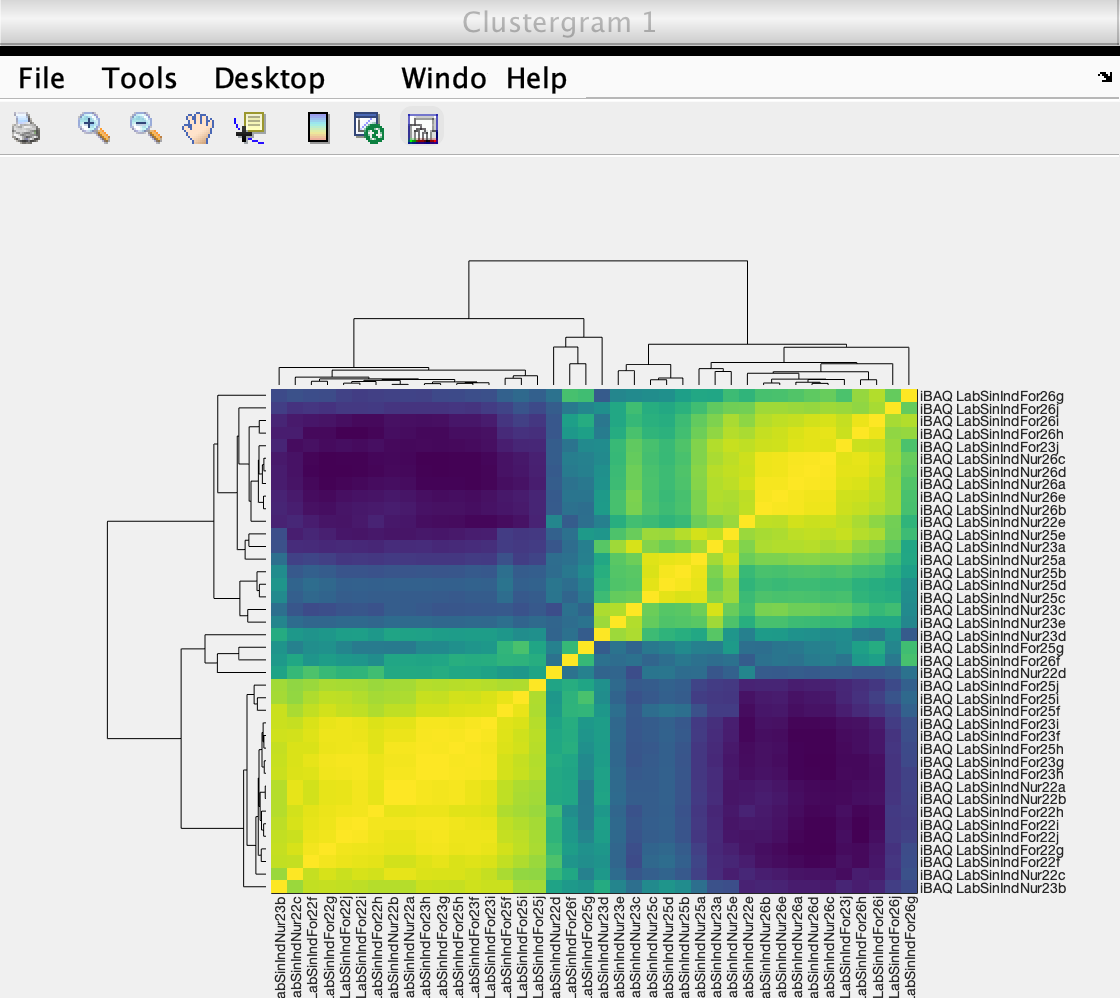

Clustergram object with 40 rows of nodes and 40 columns of nodes.




dataclean_p = bsxfun(@power,dataclean,0.5);
dataclean_minus_med = bsxfun(@minus,dataclean_p,median(dataclean_p,2));
ccdata=corrcoef(dataclean_minus_med);
eddata=pdist(dataclean_minus_med','seuclidean');

siclean_p = bsxfun(@power,siclean,0.5);
siclean_minus_med = bsxfun(@minus,siclean_p,median(siclean_p,2));
ccsi=corrcoef(siclean_minus_med);
edsi=pdist(siclean_minus_med',"seuclidean");

sis=clustergram(ccsi,'RowLabels',sampsi,'ColumnLabels',sampsi,'Standardize','none','ImputeFun', @knnimpute,'Symmetric','false','Colormap',viridis)

% organizing into the necessary matrices

yvmdatac=cat(2,dataclean(:,1:16),dataclean(:,37:63));
sampsym=cat(2,samples(:,1:16),samples(:,37:63));
fvldatac=cat(2,dataclean(:,17:36),dataclean(:,43:62));
sampfl=cat(2,samples(:,17:36),samples(:,43:62));

squirrel=~any(yvmdatac,2);
gnamesym=gnamescol;
yvmdatac(squirrel,:)=[];
gnamesym(squirrel,:)=[];

squirrel=~any(fvldatac,2);
gnamesfl=gnamescol;
fvldatac(squirrel,:)=[];
gnamesfl(squirrel,:)=[];


% square root trasnforming and median subtraction

dataclean_pym = bsxfun(@power,yvmdatac,0.5);
datacleanym_minus_med = bsxfun(@minus,dataclean_pym,median(dataclean_pym,2));
ccdataym=corrcoef(datacleanym_minus_med);
eddataym=pdist(datacleanym_minus_med',"seuclidean");

dataclean_pfl = bsxfun(@power,fvldatac,0.5);
datacleanfl_minus_med = bsxfun(@minus,dataclean_pfl,median(dataclean_pfl,2));
ccdatafl=corrcoef(datacleanfl_minus_med);
eddatafl=pdist(datacleanfl_minus_med',"seuclidean");



% Defining self similarity 

'Euclidean'

ans = 'Euclidean'

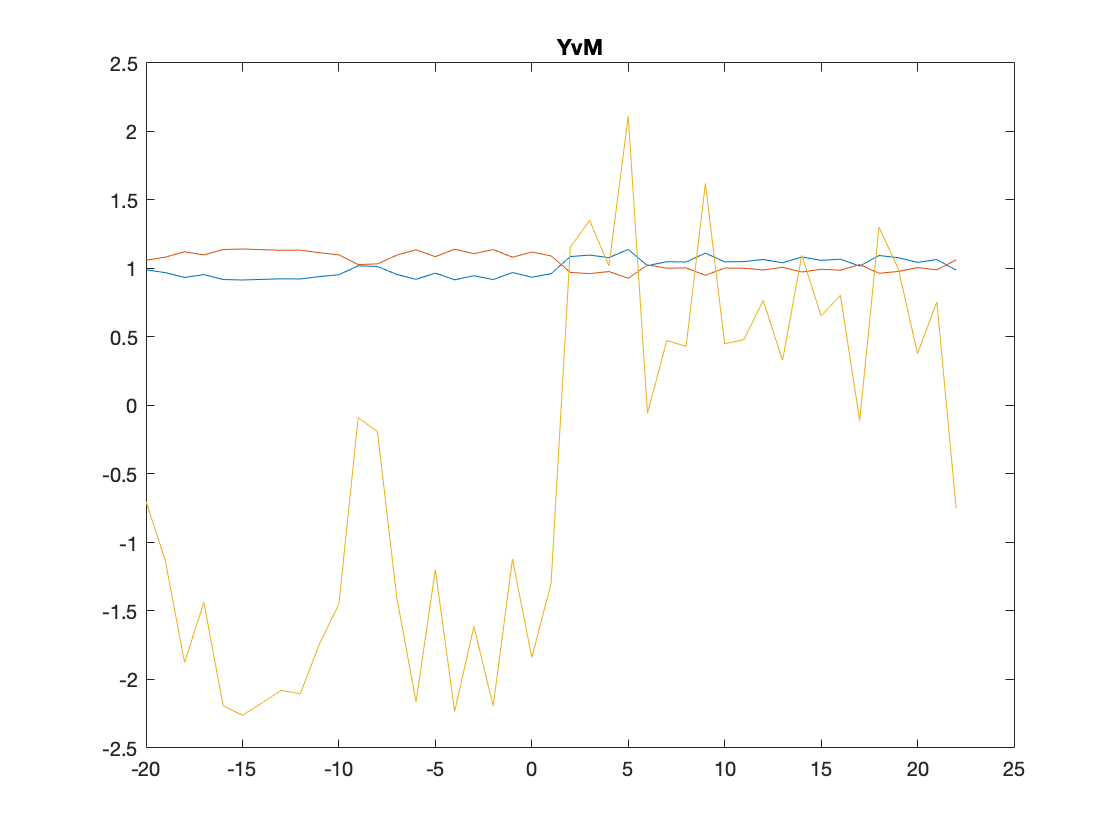

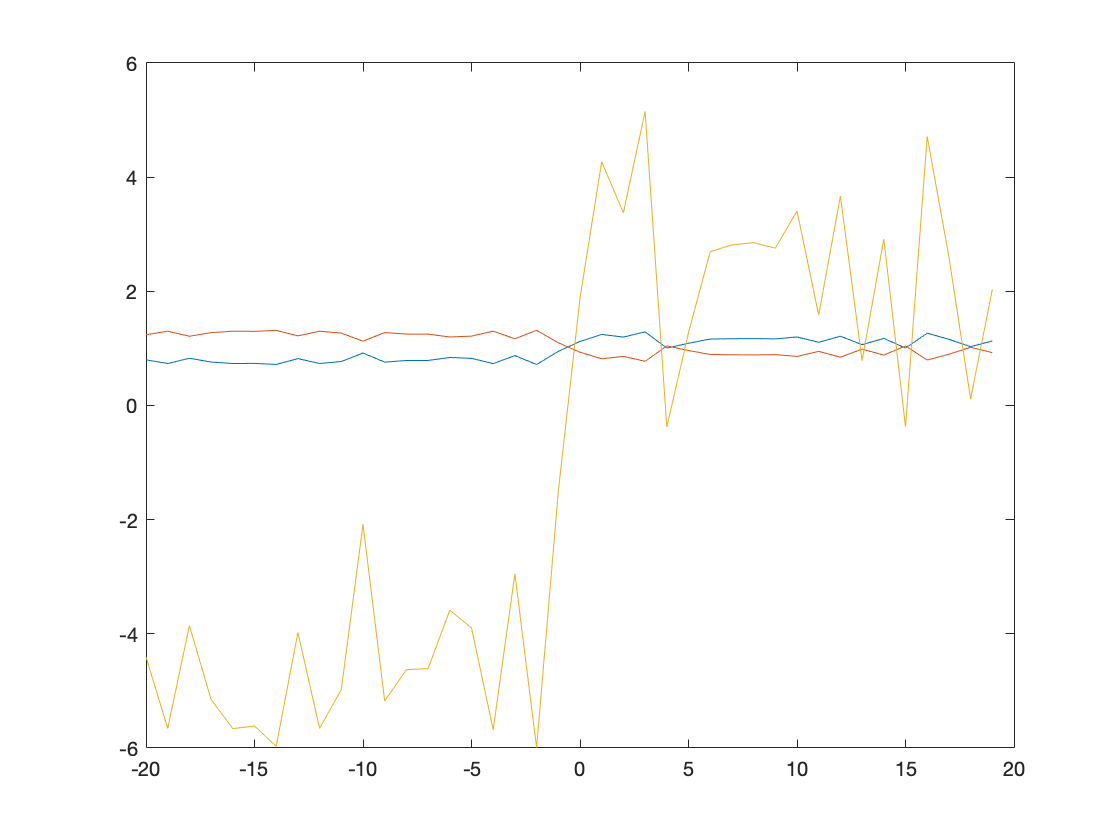

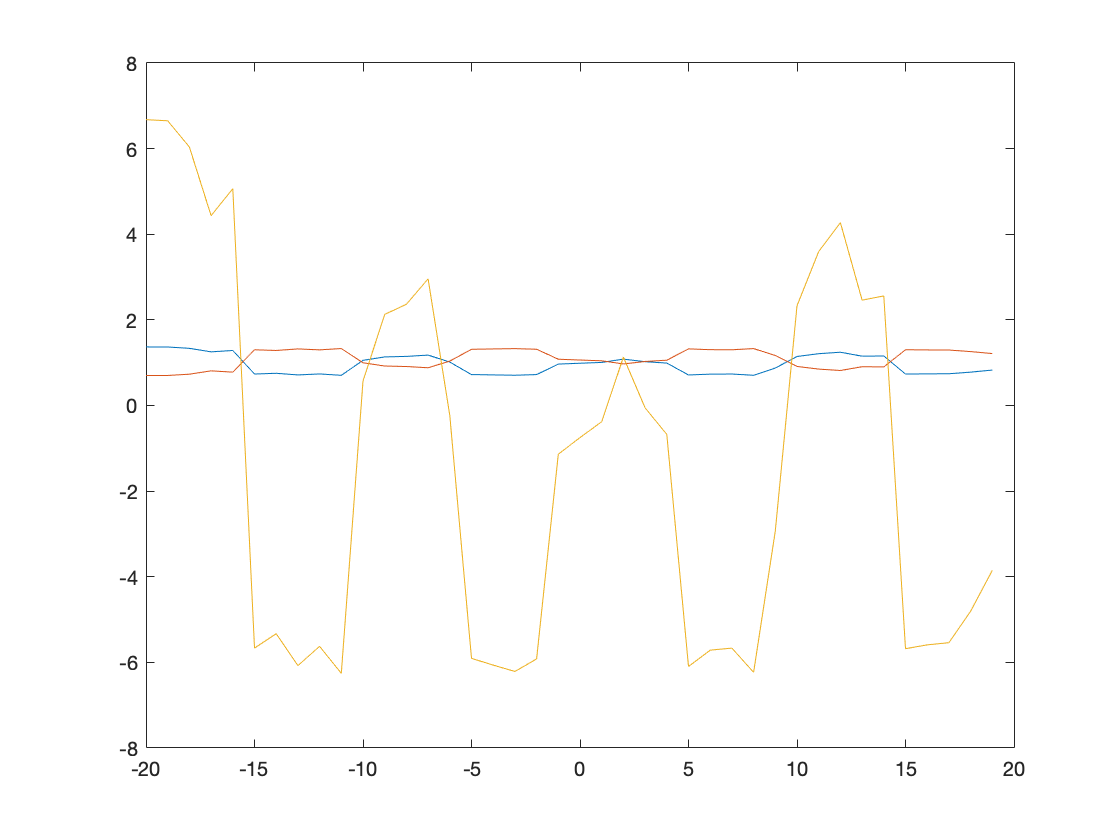

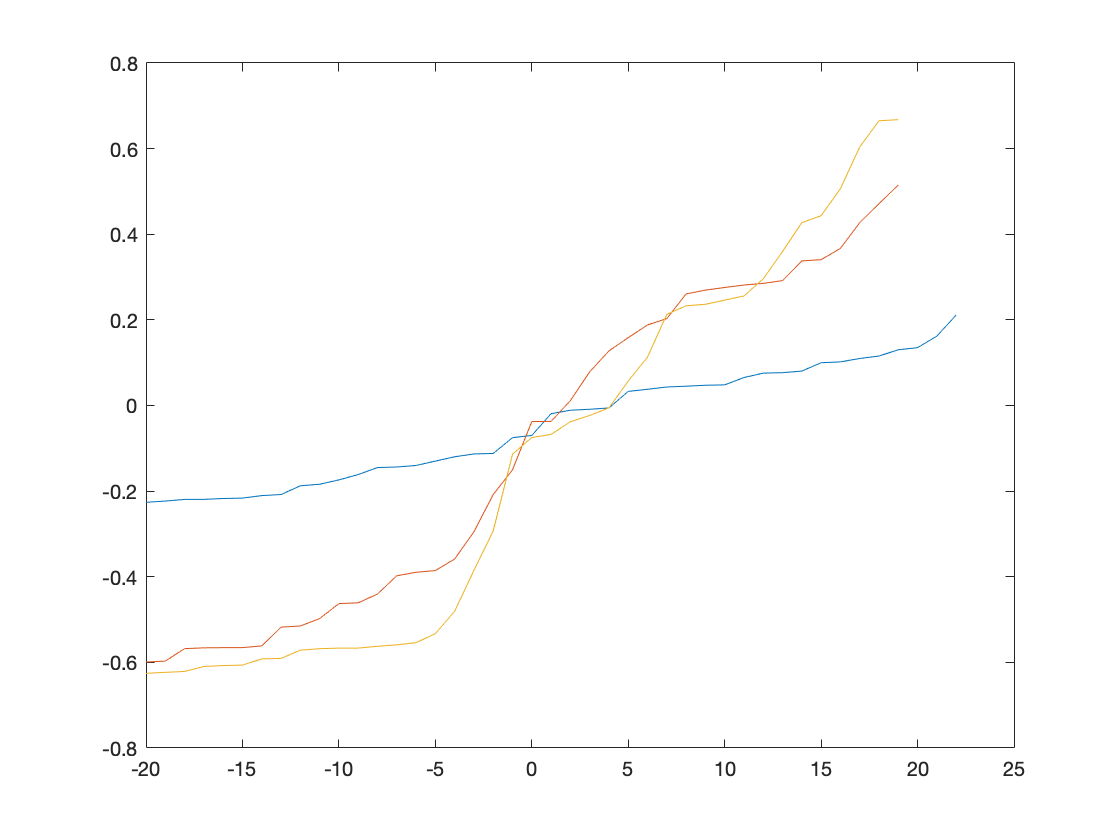

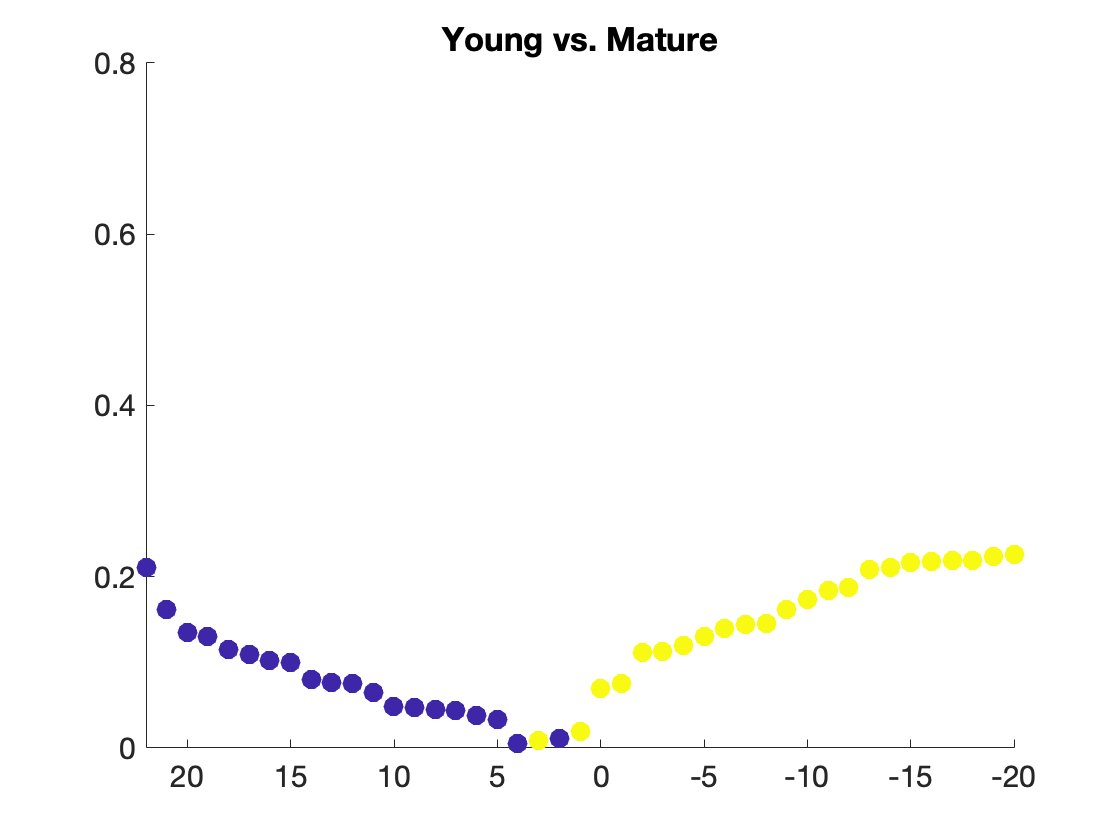

zccdataym=(squareform(eddataym)); 
zccdatafl=(squareform(eddatafl));
zccsi=(squareform(edsi));
altym=[];altfl=[];altnf=[];

for i=1:43
    now=zccdataym(i,isfinite(zccdataym(i,:)));
    nowclass=classym; 
    if classym(i)==1 %if mature
        sameclass(i)=((sum(now.*nowclass))/22)/mean(now); %aver of all mature EDs
        otherclass(i)=((sum(now.*(abs(nowclass-1))))/20)/mean(now); %aver of young EDs
        allclass(i)=mean(now);
    else  %if young
        otherclass(i)=((sum(now.*nowclass))/23)/mean(now);  %aver of all young EDs
        sameclass(i)=((sum(now.*(abs(nowclass-1))))/19)/mean(now);
        allclass(i)=mean(now);
    end
    altym(i)=(sameclass(i)-otherclass(i));
end
figure;
plot([-20:22],(sameclass))
hold on
plot([-20:22],(otherclass))
hold on
plot([-20:22],(10.*altym))
title('YvM')

sameclass=[];otherclass=[];allclass=[];
for i=1:40
    now=zccdatafl(i,isfinite(zccdatafl(i,:)));
    nowclass=classfl; 
    if classfl(i)==0 %if field
        otherclass(i)=((sum(now.*nowclass))/20)/mean(now);
        sameclass(i)=((sum(now.*(abs(nowclass-1))))/19)/mean(now);                
        allclass(i)=mean(now);

    else %if lab
        sameclass(i)=((sum(now.*nowclass))/19)/mean(now);
        otherclass(i)=((sum(now.*(abs(nowclass-1))))/20)/mean(now);
        allclass(i)=mean(now);
    end
    altfl(i)=(sameclass(i)-otherclass(i));
end

figure 
plot([-20:19],(sameclass))
hold on
plot([-20:19],(otherclass))
hold on
plot([-20:19],(10.*altfl))
sameclass=[];otherclass=[];allclass=[];


for i=1:40

    now=zccsi(i,isfinite(zccsi(i,:)));
    nowclass=classnf; 
    if classnf(i)==0 %if nurse
        otherclass(i)=((sum(now.*nowclass))/20)/mean(now);
        sameclass(i)=((sum(now.*(abs(nowclass-1))))/19)/mean(now);
        allclass(i)=mean(now);
    else
        sameclass(i)=((sum(now.*nowclass))/19)/mean(now);
        otherclass(i)=((sum(now.*(abs(nowclass-1))))/20)/mean(now);
        allclass(i)=mean(now);
    end
    altnf(i)=(sameclass(i)-otherclass(i));
end

figure 
plot([-20:19],(sameclass))
hold on
plot([-20:19],(otherclass))
hold on
plot([-20:19],(10.*altnf))

figure
plot([-20:22],sort(altym))
hold on
plot([-20:19],sort(altfl))
hold on
plot([-20:19],sort(altnf))

ym=cat(1,(altym),classym); ym=ym'; ym=sortrows(ym);
fl=cat(1,(altfl),classfl); fl=fl'; fl=sortrows(fl);
nf=cat(1,(altnf),classnf); nf=nf'; nf=sortrows(nf);

figure;
scatter([-20:22],abs(ym(:,1)),100,ym(:,2),'filled')
title('Young vs. Mature')
set(gca, 'XDir','reverse')
axis([-20 22 0 0.8])
yticks([0 .2 .4 .6 .8])
ax = gca;
ax.FontSize = 15;
print('YvMgradient','-depsc','-r200','-painters')

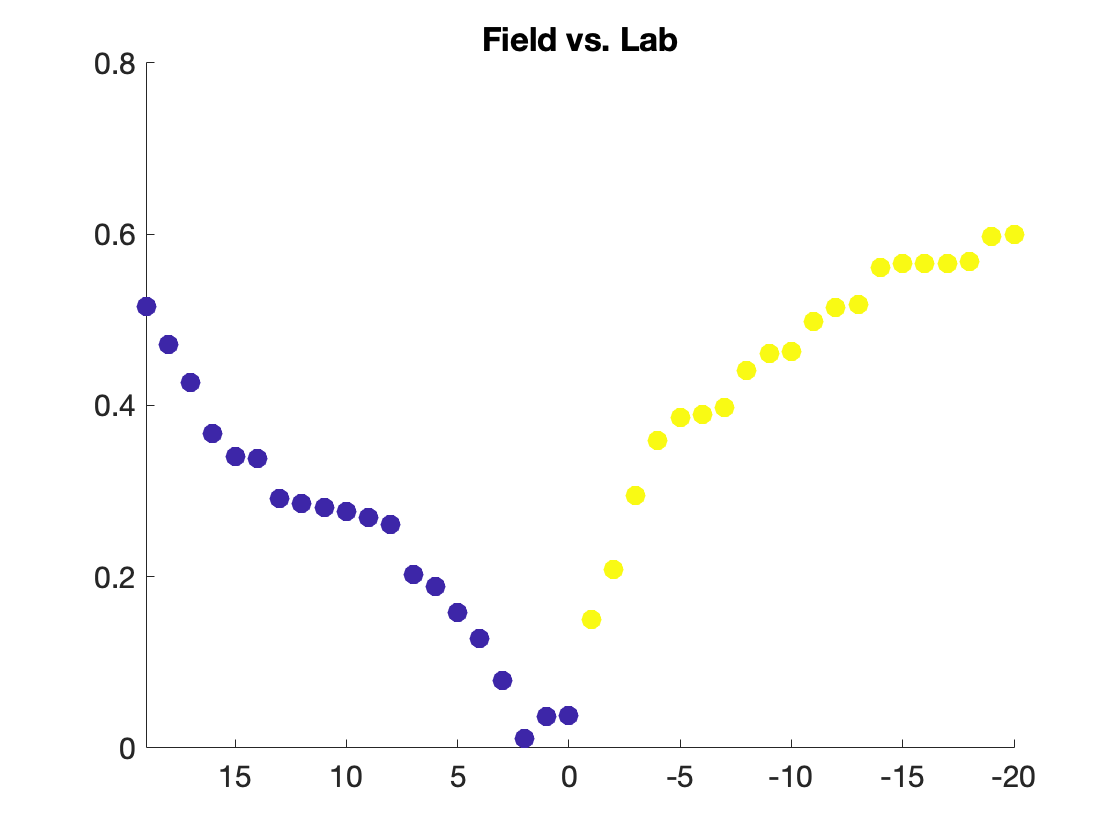

figure;
scatter([-20:19],abs(fl(:,1)),100,fl(:,2),'filled')
title('Field vs. Lab')
set(gca, 'XDir','reverse')
axis([-20 19 0 .8])
yticks([0 .2 .4 .6 .8])
ax = gca;
ax.FontSize = 15;
print('FvLgradient','-depsc','-r200','-painters')

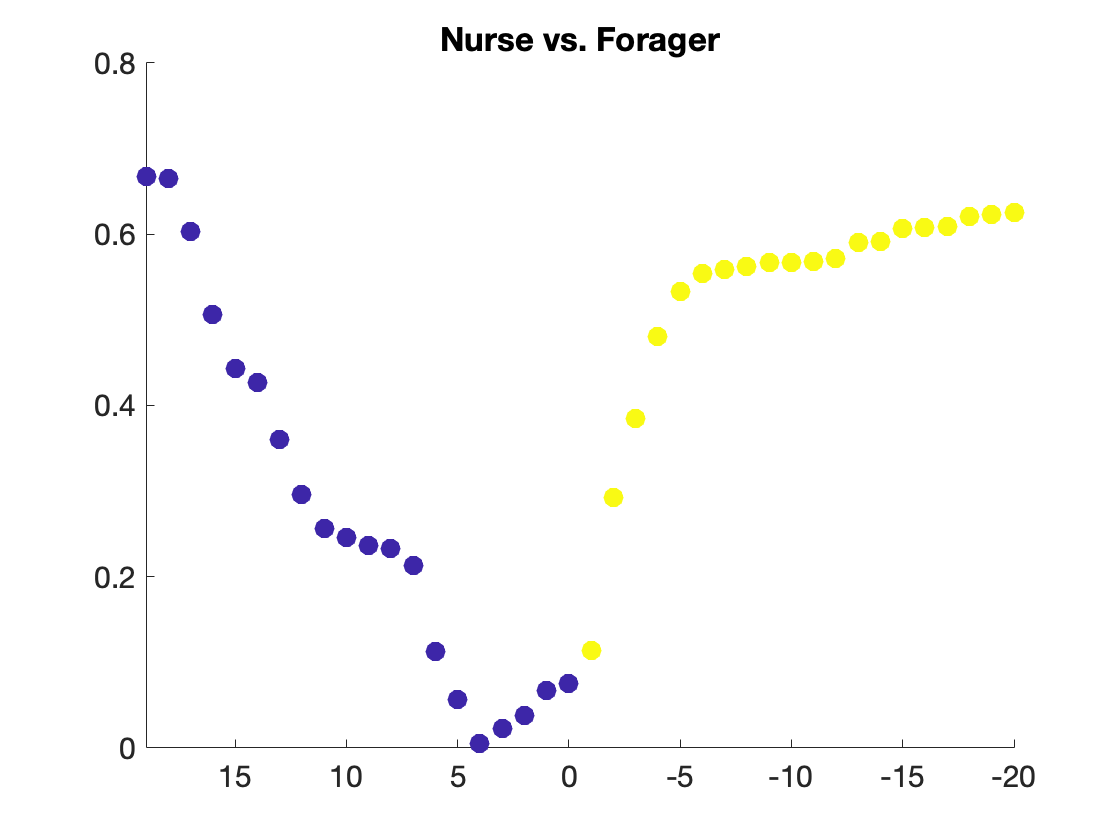

figure;
scatter([-20:19],abs(nf(:,1)),100,nf(:,2),'filled')
set(gca, 'XDir','reverse')
title('Nurse vs. Forager')
axis([-20 19 0 .8])
yticks([0 .2 .4 .6 .8])
ax = gca;
ax.FontSize = 15;
print('NvFgradient','-depsc','-r200','-painters')

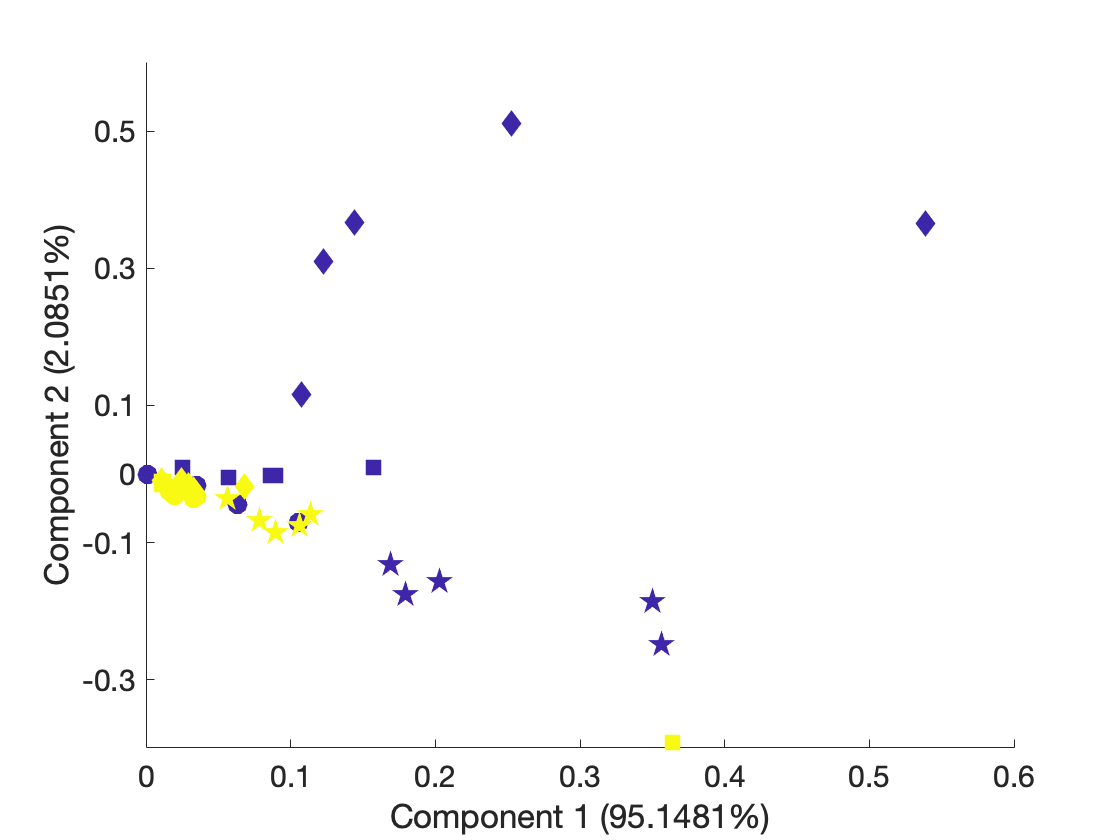

% plotting PCAs


figure
[Y,siscore,silatent,sitsquared,siexplained,simu]=pca(siclean);
scatter(Y(1:10,1),Y(1:10,2),100,classnf(1:10),'o','filled')
hold on
scatter(Y(11:20,1),Y(11:20,2),100,classnf(11:20),'s','filled')
hold on
scatter(Y(21:30,1),Y(21:30,2),100,classnf(21:30),'d','filled')
hold on
scatter(Y(31:40,1),Y(31:40,2),200,classnf(31:40),'p','filled')
ax = gca;
ax.FontSize = 15;
xticks([0 .1 .2 .3 0.4 0.5 .6])
yticks([-.3 -.1 0 .1 .3 .5])
xlabel(['Component 1 (',num2str(siexplained(1)),'%)'])
ylabel(['Component 2 (',num2str(siexplained(2)),'%)'])
print('PCAsi','-depsc','-r200','-painters')

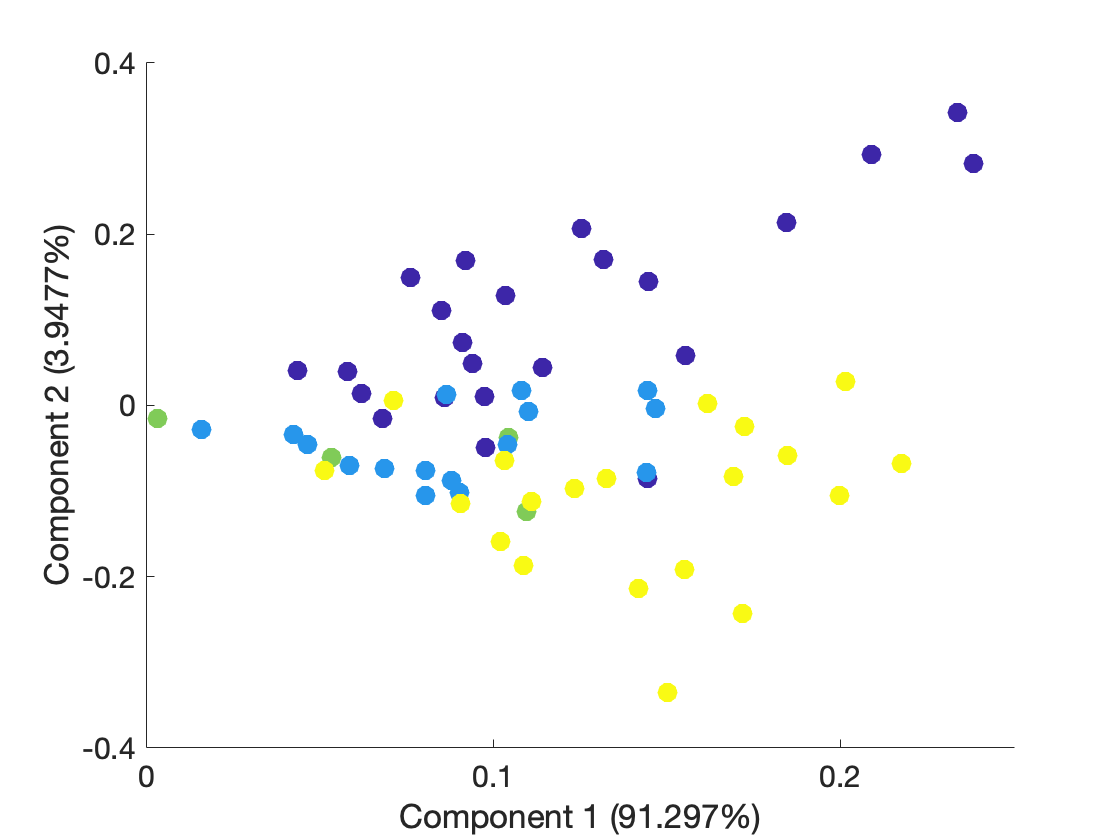


pcacoeff_si=Y;

figure
[Y,pscore,platent,ptsquared,pexplained,pmu]=pca(dataclean);
scatter(Y(:,1),Y(:,2),100,classpooled,'o','filled')

pcacoeff_p=Y;
ax = gca;
ax.FontSize = 15;
xticks([0 .1 .2 .3])
yticks([-.4 -.2 0 .2 .4])
xlabel(['Component 1 (',num2str(pexplained(1)),'%)'])
ylabel(['Component 2 (',num2str(pexplained(2)),'%)'])
print('PCApooled','-depsc','-r200','-painters')

SSym=abs(ym);
SSnf=abs(nf);
SSfl=abs(fl);
writematrix(SSym,'Figure3_SourceData.xlsx','Sheet',1);
writematrix(SSnf,'Figure3_SourceData.xlsx','Sheet',2);

writematrix(SSfl,'Figure3_SourceData.xlsx','Sheet',3);

writematrix(pcacoeff_si,'Figure3_SourceData.xlsx','Sheet',4);

writematrix(pcacoeff_p,'Figure3_SourceData.xlsx','Sheet',5);